hold off;
x_points=4999;

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ";";

% Specify column names and types
opts.VariableNames = ["Workload", "Exit", "Single_record", "Single_replay", "Diff", "Cumulative_record", "Cumulative_replay"];
opts.VariableTypes = ["categorical", "categorical", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Workload", "Exit"], "EmptyFieldRule", "auto");

% Import the data
effectivenessresults = readtable("effectiveness_results.csv", opts);


coverage_recording=effectivenessresults.Cumulative_record(effectivenessresults.Workload=='OS-BOOT');
plot(0:x_points,[0 coverage_recording(1:x_points)'], '-','LineWidth',3)
hold on;
coverage_replaying=effectivenessresults.Cumulative_replay(effectivenessresults.Workload=='OS-BOOT');
plot(0:x_points,[0 coverage_replaying(1:x_points)'], '-.','LineWidth',3)
%plot(0:x_points,[0 effectivenessresults.Diff(effectivenessresults.Workload=='OS-BOOT')'], '-','LineWidth',0.1)
%legend({'recording','replaying'})
%names = {'REAL'; 'PROTECTED'; ''};
%set(gca,'xtick',[1:5],'xticklabel',names)
coverage_replaying(4999)/coverage_recording(4999)

ans = 0.9896

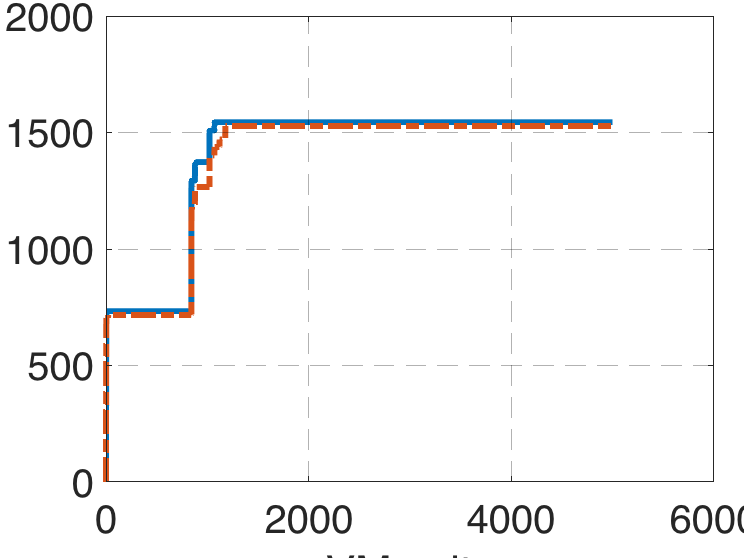

xlabel("VM exits");
ylabel("Code coverage");
%xlim([0.44 2.71])
ylim([0 2000])
ax = gca; 
ax.FontSize = 20;
%legend({'recording','replaying'},'Orientation',"horizontal","Location","south")
%set(gca, 'YScale', 'log')
grid on
ax = gca;
ax.GridColor = [0 0 0];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.3;
ax.Layer = 'top';


%save figure
outerpos = ax.OuterPosition;
ti = ax.TightInset;
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];
a2 = gcf;
a2.PaperPositionMode = 'auto';
fig_pos = a2.PaperPosition;
a2.PaperSize = [fig_pos(3) fig_pos(4)];
print(a2, strcat(fileparts(pwd),'/figures/BOOT_cum_cov.pdf'),'-dpdf','-r0');